clear;close all;clc
s=tf('s','TimeUnit','seconds');
Ts=60*5; % Sampling = 5 min (denoted in seconds) 



theta=5*60;
ptilde=(1/s)*exp(-theta*s)

ptilde =
 
                1
  exp(-300*s) * -
                s
 
Continuous-time transfer function.




pdel=ptilde.InputDelay;
[z_pt,p_pt,k_pt]=zpkdata(ptilde);
z_pt_nonmin=z_pt{1}(find(real(z_pt{:})>0));
z_pt_min=z_pt{1}(find(real(z_pt{:})<=0));

p_nonmin=zpk(z_pt_nonmin,[],1)*exp(-pdel*s)%nonmin of ptilte

p_nonmin =
 
  exp(-3e+02*s) * 1
 
Continuous-time zero/pole/gain model.



p_min=zpk(z_pt_min,p_pt,k_pt,'TimeUnit','seconds')%min of ptilte

p_min =
 
  1
  -
  s
 
Continuous-time zero/pole/gain model.



% p_min=1/s;


qtilde=(theta*s+1)/p_min

qtilde =
 
  300 s (s+0.003333)
 
Continuous-time zero/pole/gain model.



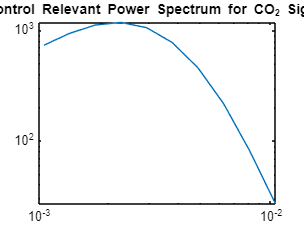


lambda=4.99*60; %minutes, multiplication with 60 generates secs

nf=4;
filt=(nf*lambda*s+1)/(lambda*s+1)^nf;
qtot=qtilde*filt;
eta=minreal(ptilde*qtot);
% eta=minreal(p_nonmin*(1/s)*qtot)
epsilon=1-eta;
dist=1/s^2;

Av_func=epsilon*dist*(qtot); % prefilter eqn

%     Av_func.TimeUnit='minutes';


% opts=bodeoptions;
% opts.MagUnits='abs';
% opts.MagScale='log';
% opts.Xlim=[0.0001,100];
% figure;bodemag(Av_func,opts);title(['Relative Magnitudes of the frequencies'])

Day_Start=9;
Day_End=19;
Nhour=(Day_End-Day_Start);

n_cyc=6;
Ns=Nhour*60*60/n_cyc/Ts; %Length of the sequence( 12 hours of data)
ns=ceil(Ns/2);

omegavec=logspace(log10(2*pi/Ns/Ts),log10(pi/Ts),ns);
% omegavec = logspace(-4,-1,12);
magval=freqresp(Av_func,omegavec);

magval=magval(:); 
magval_abs=abs(magval);
powval_abs=magval_abs.^2;

figure;loglog(omegavec,magval_abs);title('Control Relevant Power Spectrum for CO_2 Signal')

MultisineFrequencies=magval_abs

MultisineFrequencies = 	1.0e+03 *

    0.7328
    0.9384
    1.1165
    1.1794
    1.0564
    0.7745
    0.4566
    0.2158
    0.0820
    0.0274


% save MultisineFrequencies.mat MultisineFrequencies
% save mag_speed_5_ts_5_mins_Nhour_10_n_cyc_6.mat magval_abs

% call sig generator script now
p_spec = [omegavec' magval_abs]

p_spec = 	1.0e+03 *

    0.0000    0.7328
    0.0000    0.9384
    0.0000    1.1165
    0.0000    1.1794
    0.0000    1.0564
    0.0000    0.7745
    0.0000    0.4566
    0.0000    0.2158
    0.0000    0.0820
    0.0000    0.0274


% save mag_speed_3_ts_5_60_mins_freq.mat p_spec


% Main_MultiSin_LS

% tvec=hours(9):minutes(1):hours(20);
% figure;
% subplot(4,1,1);plot(tvec,io_iddat.y)
% xtickformat('hh:mm:ss')
% subplot(4,1,2);plot(tvec,io_iddat.u(:,1)*(60*1000))
% xtickformat('hh:mm:ss')
% subplot(4,1,3);plot(tvec,io_iddat.u(:,2))
% xtickformat('hh:mm:ss')
% subplot(4,1,4);plot(tvec,io_iddat.u(:,3))
% xtickformat('hh:mm:ss')
% 
% figure;
% subplot(5,1,1);plot(tvec,io_iddat.y)
% xtickformat('hh:mm:ss')
% subplot(5,1,2);plot(tvec,io_iddat.u(:,1)*(60*1000))
% xtickformat('hh:mm:ss')
% subplot(5,1,3);plot(tvec,io_iddat.u(:,2))
% xtickformat('hh:mm:ss')
% subplot(5,1,4);plot(tvec,io_iddat.u(:,3))
% xtickformat('hh:mm:ss')
% subplot(5,1,5);plot(tvec,io_iddat.u(:,3))
% xtickformat('hh:mm:ss')

